## Example: Linear Inequality and Equality constraint

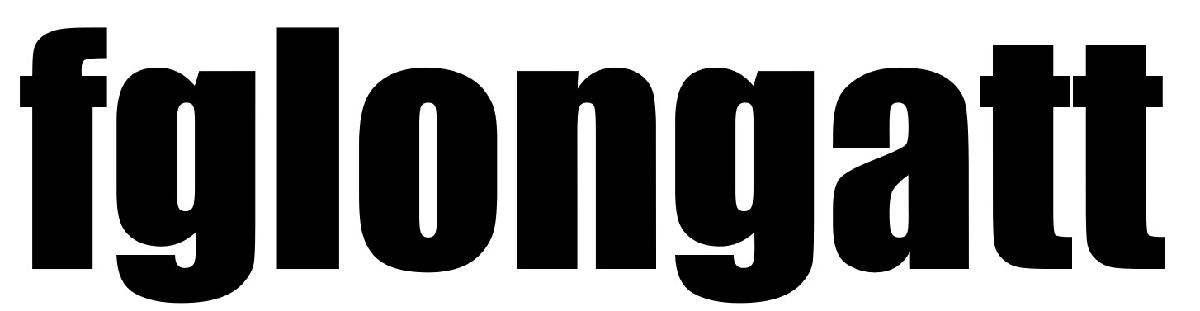  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

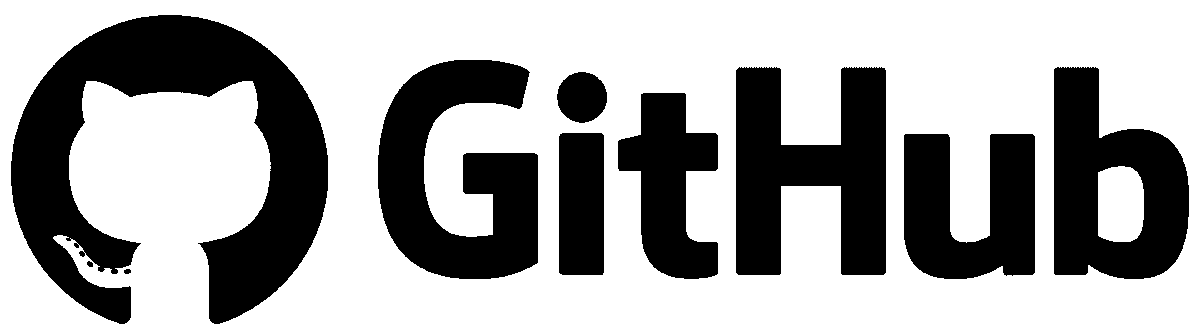 [https://github.com/fglongatt](https://github.com/fglongatt) 

Minimise the following two variable objective function:


$$f\left(x_1 ,x_2 \right)=x_1^2 +4x_2^2$$


Subject to the constraint:


$$x_1 +x_2 -4=0$$


### Solution

Initially the symbolic mathematic in MATLAB is used to plot the three dimension function

syms x_1 x_2
f = x_1^2 + 4*x_2^2

$$f = {x_{1}}^{2}+4\,{x_{2}}^{2}$$

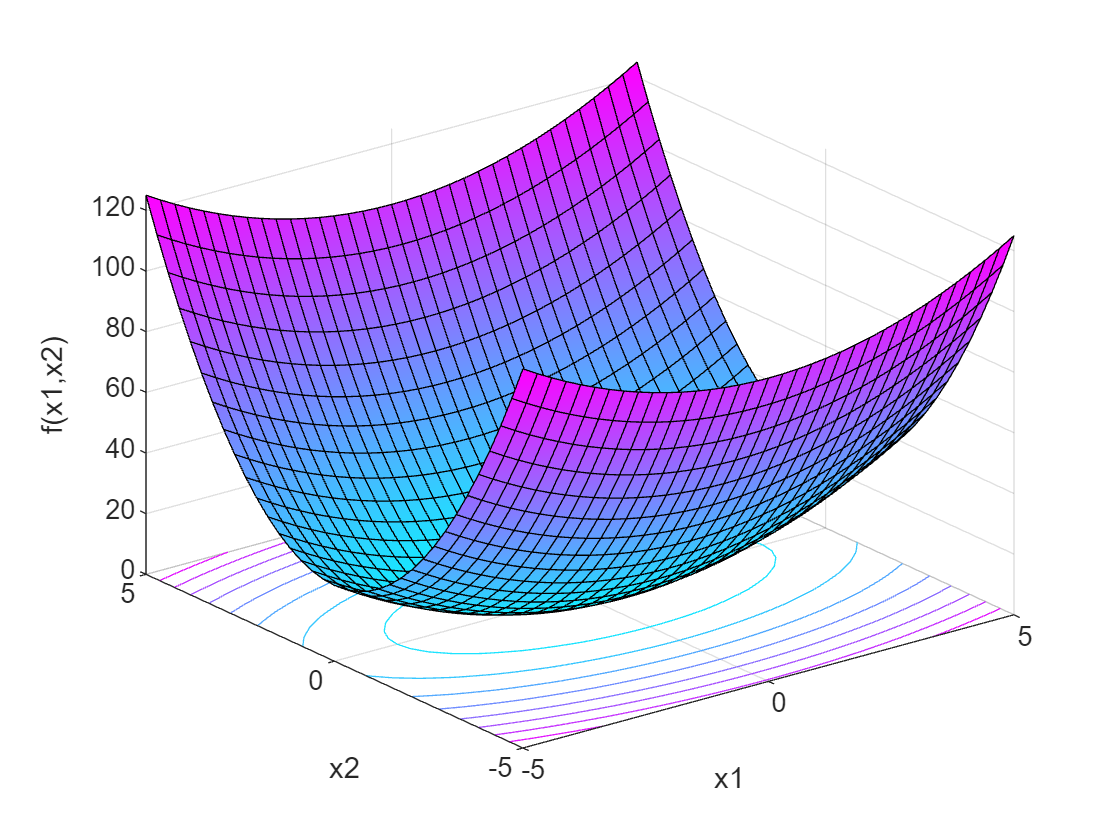

colormap cool
fsurf(f,'ShowContours','on')
xlabel('x1')
ylabel('x2')
zlabel('f(x1,x2)')

**Step 1: **The objective function must be define as a function isnide the script. A function hanlde can be used.

A function handle in MTALAB is a data type that stores an associaitoon to a fucntion.

fun = @(x)x(1)^2 + 4*x(2)^2;    % Objective function

**Step 2: **Define initial conditions for the vector **x**:

x0 = [-5,-5]

x0 =     -5    -5


**Step 3:** Define the matrix and vector or the **inequaility contraint**:


$$\textrm{Ax}\le \mathit{\mathbf{b}}$$


In this problem there is not inequality constraint:

A=[];
b=[];

**Step 4: **Defining **the equality constraint:**


$${\mathbf{A}}_{\textrm{eq}} \mathit{\mathbf{x}}={\mathit{\mathbf{b}}}_{\textrm{eq}}$$


In this problem:

$x_1 +x_2 -4=0$  rewriting:  $x_1 +x_2 =4$


$$\left\lbrack \begin{array}{cc}
1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack 4\right\rbrack$$


${\mathbf{A}}_{\textrm{eq}}$=$\left\lbrack \begin{array}{cc}
1 & 1
\end{array}\right\rbrack$

${\mathit{\mathbf{b}}}_{\textrm{eq}}$ =$\left\lbrack 4\right\rbrack$

Aeq =[1, 1]

Aeq =      1     1


beq =4;
lb=[];
ub=[];
NONlin =[]


NONlin =

     []



**Step 5**: Excecuting the optimiSation

options = optimoptions('fmincon','Display','iter')

options =   fmincon options:

   Options used by current Algorithm ('interior-point'):
   (Other available algorithms: 'active-set', 'sqp', 'sqp-legacy', 'trust-region-reflective')

   Set properties:
                      Display: 'iter'

   Default properties:
                    Algorithm: 'interior-point'
           BarrierParamUpdate: 'monotone'
          ConstraintTolerance: 1.0000e-06
        EnableFeasibilityMode: 0
     FiniteDifferenceStepSize: 'sqrt(eps)'
         FiniteDifferenceType: 'forward'
         HessianApproximation: 'bfgs'
                   HessianFcn: []
           HessianMultiplyFcn: []
                  HonorBounds: 1
       MaxFunctionEvaluations: 3000
                MaxIterations: 1000
               ObjectiveLimit: -1.0000e+20
          OptimalityTolerance: 1.0000e-06
              

[x,fval,exitflag,output] = fmincon(fun,x0,A,b,Aeq,beq,...
    lb,ub,NONlin,options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.250000e+02    1.400e+01    1.500e+01
    1       8    5.000000e+01    1.050e+01    2.725e+01    5.852e+00
    2      11    1.540224e+01    4.441e-16    1.134e+01    1.093e+01
    3      14    1.280799e+01    4.441e-16    4.159e-01    1.077e+00
    4      17    1.280000e+01    0.000e+00    4.979e-08    5.655e-02

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the 

x =     3.2000    0.8000


fval = 12.8000

exitflag = 1

output = struct with fields:
         iterations: 4
          funcCount: 17
    constrviolation: 0
           stepsize: 0.0565
          algorithm: 'interior-point'
      firstorderopt: 4.9786e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 7.779115e-09,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


Be part of our community 

 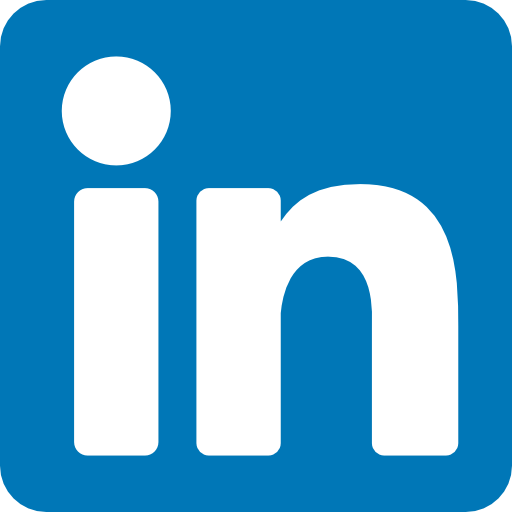 [https://www.linkedin.com/in/francisco-gonzalez-longatt/](https://www.linkedin.com/in/francisco-gonzalez-longatt/) 

 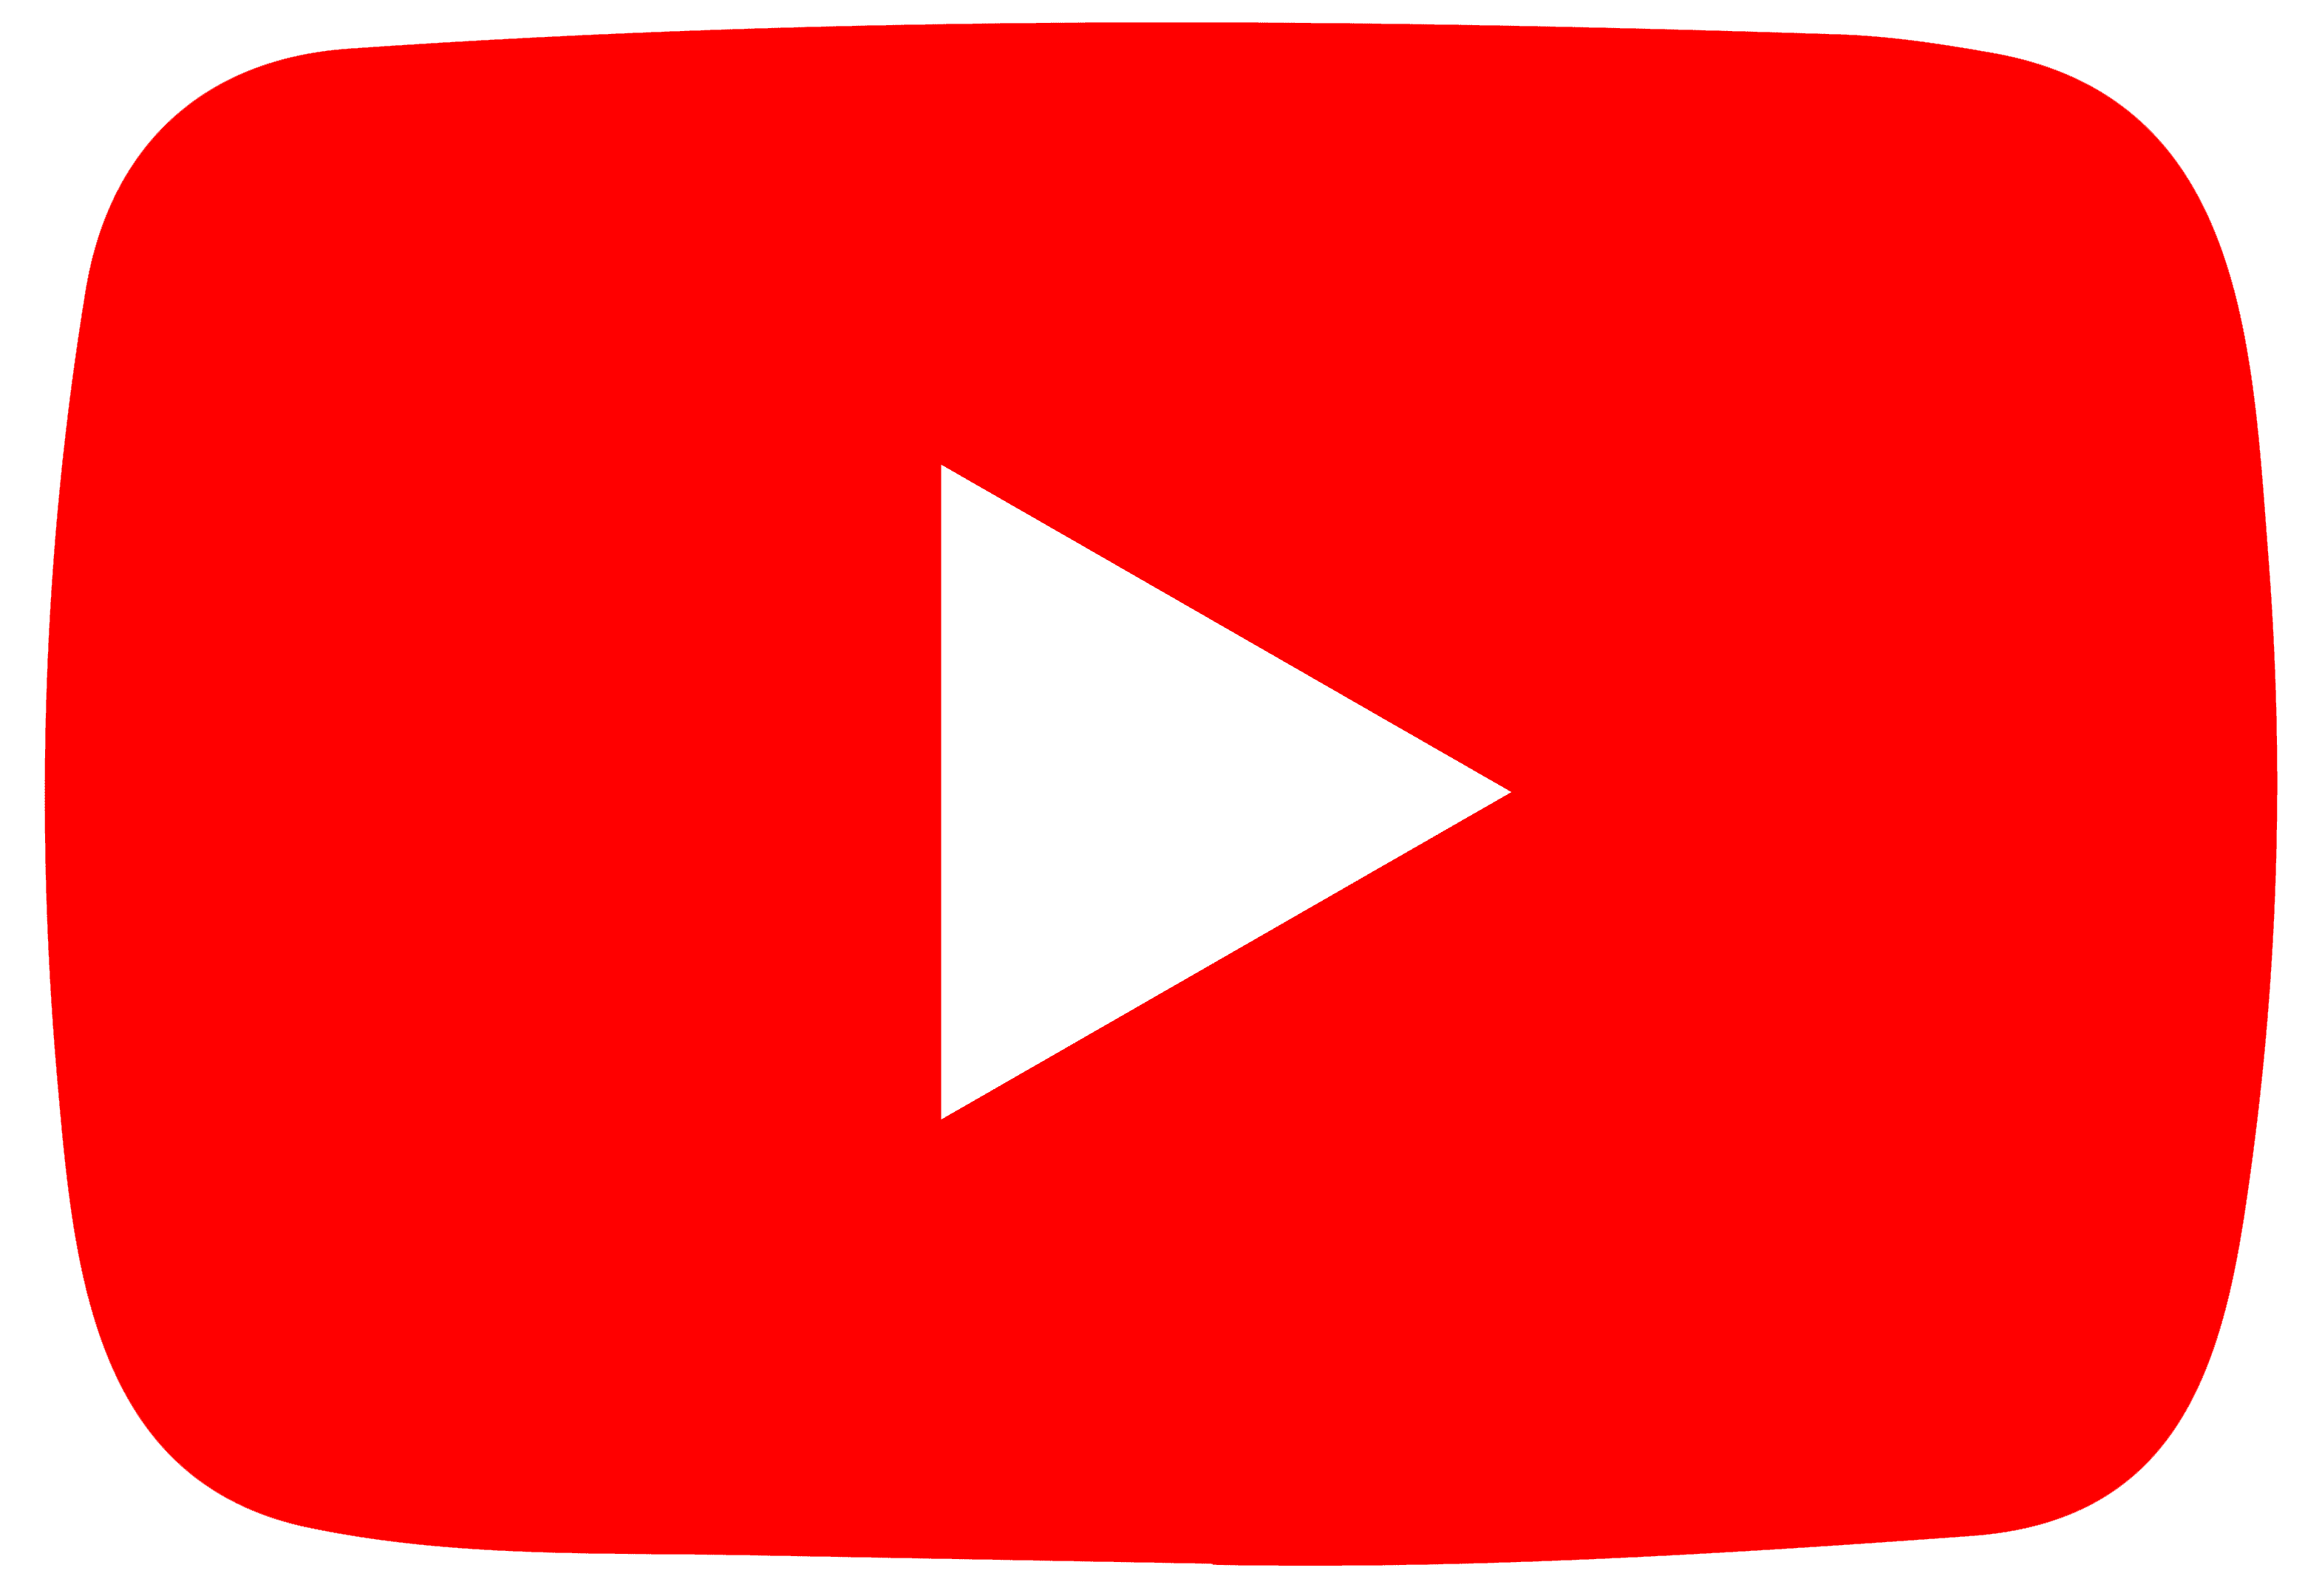 [https://www.youtube.com/user/fmglongatt](https://www.youtube.com/user/fmglongatt) 

 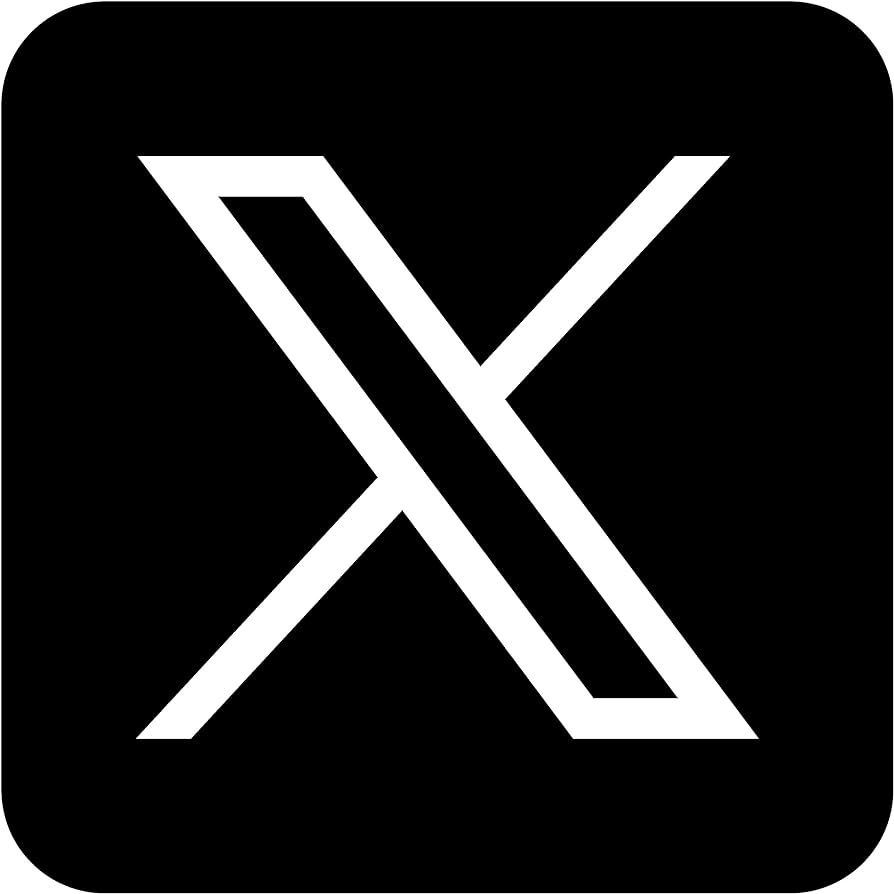  [https://twitter.com/fglongatt](https://twitter.com/fglongatt) 

 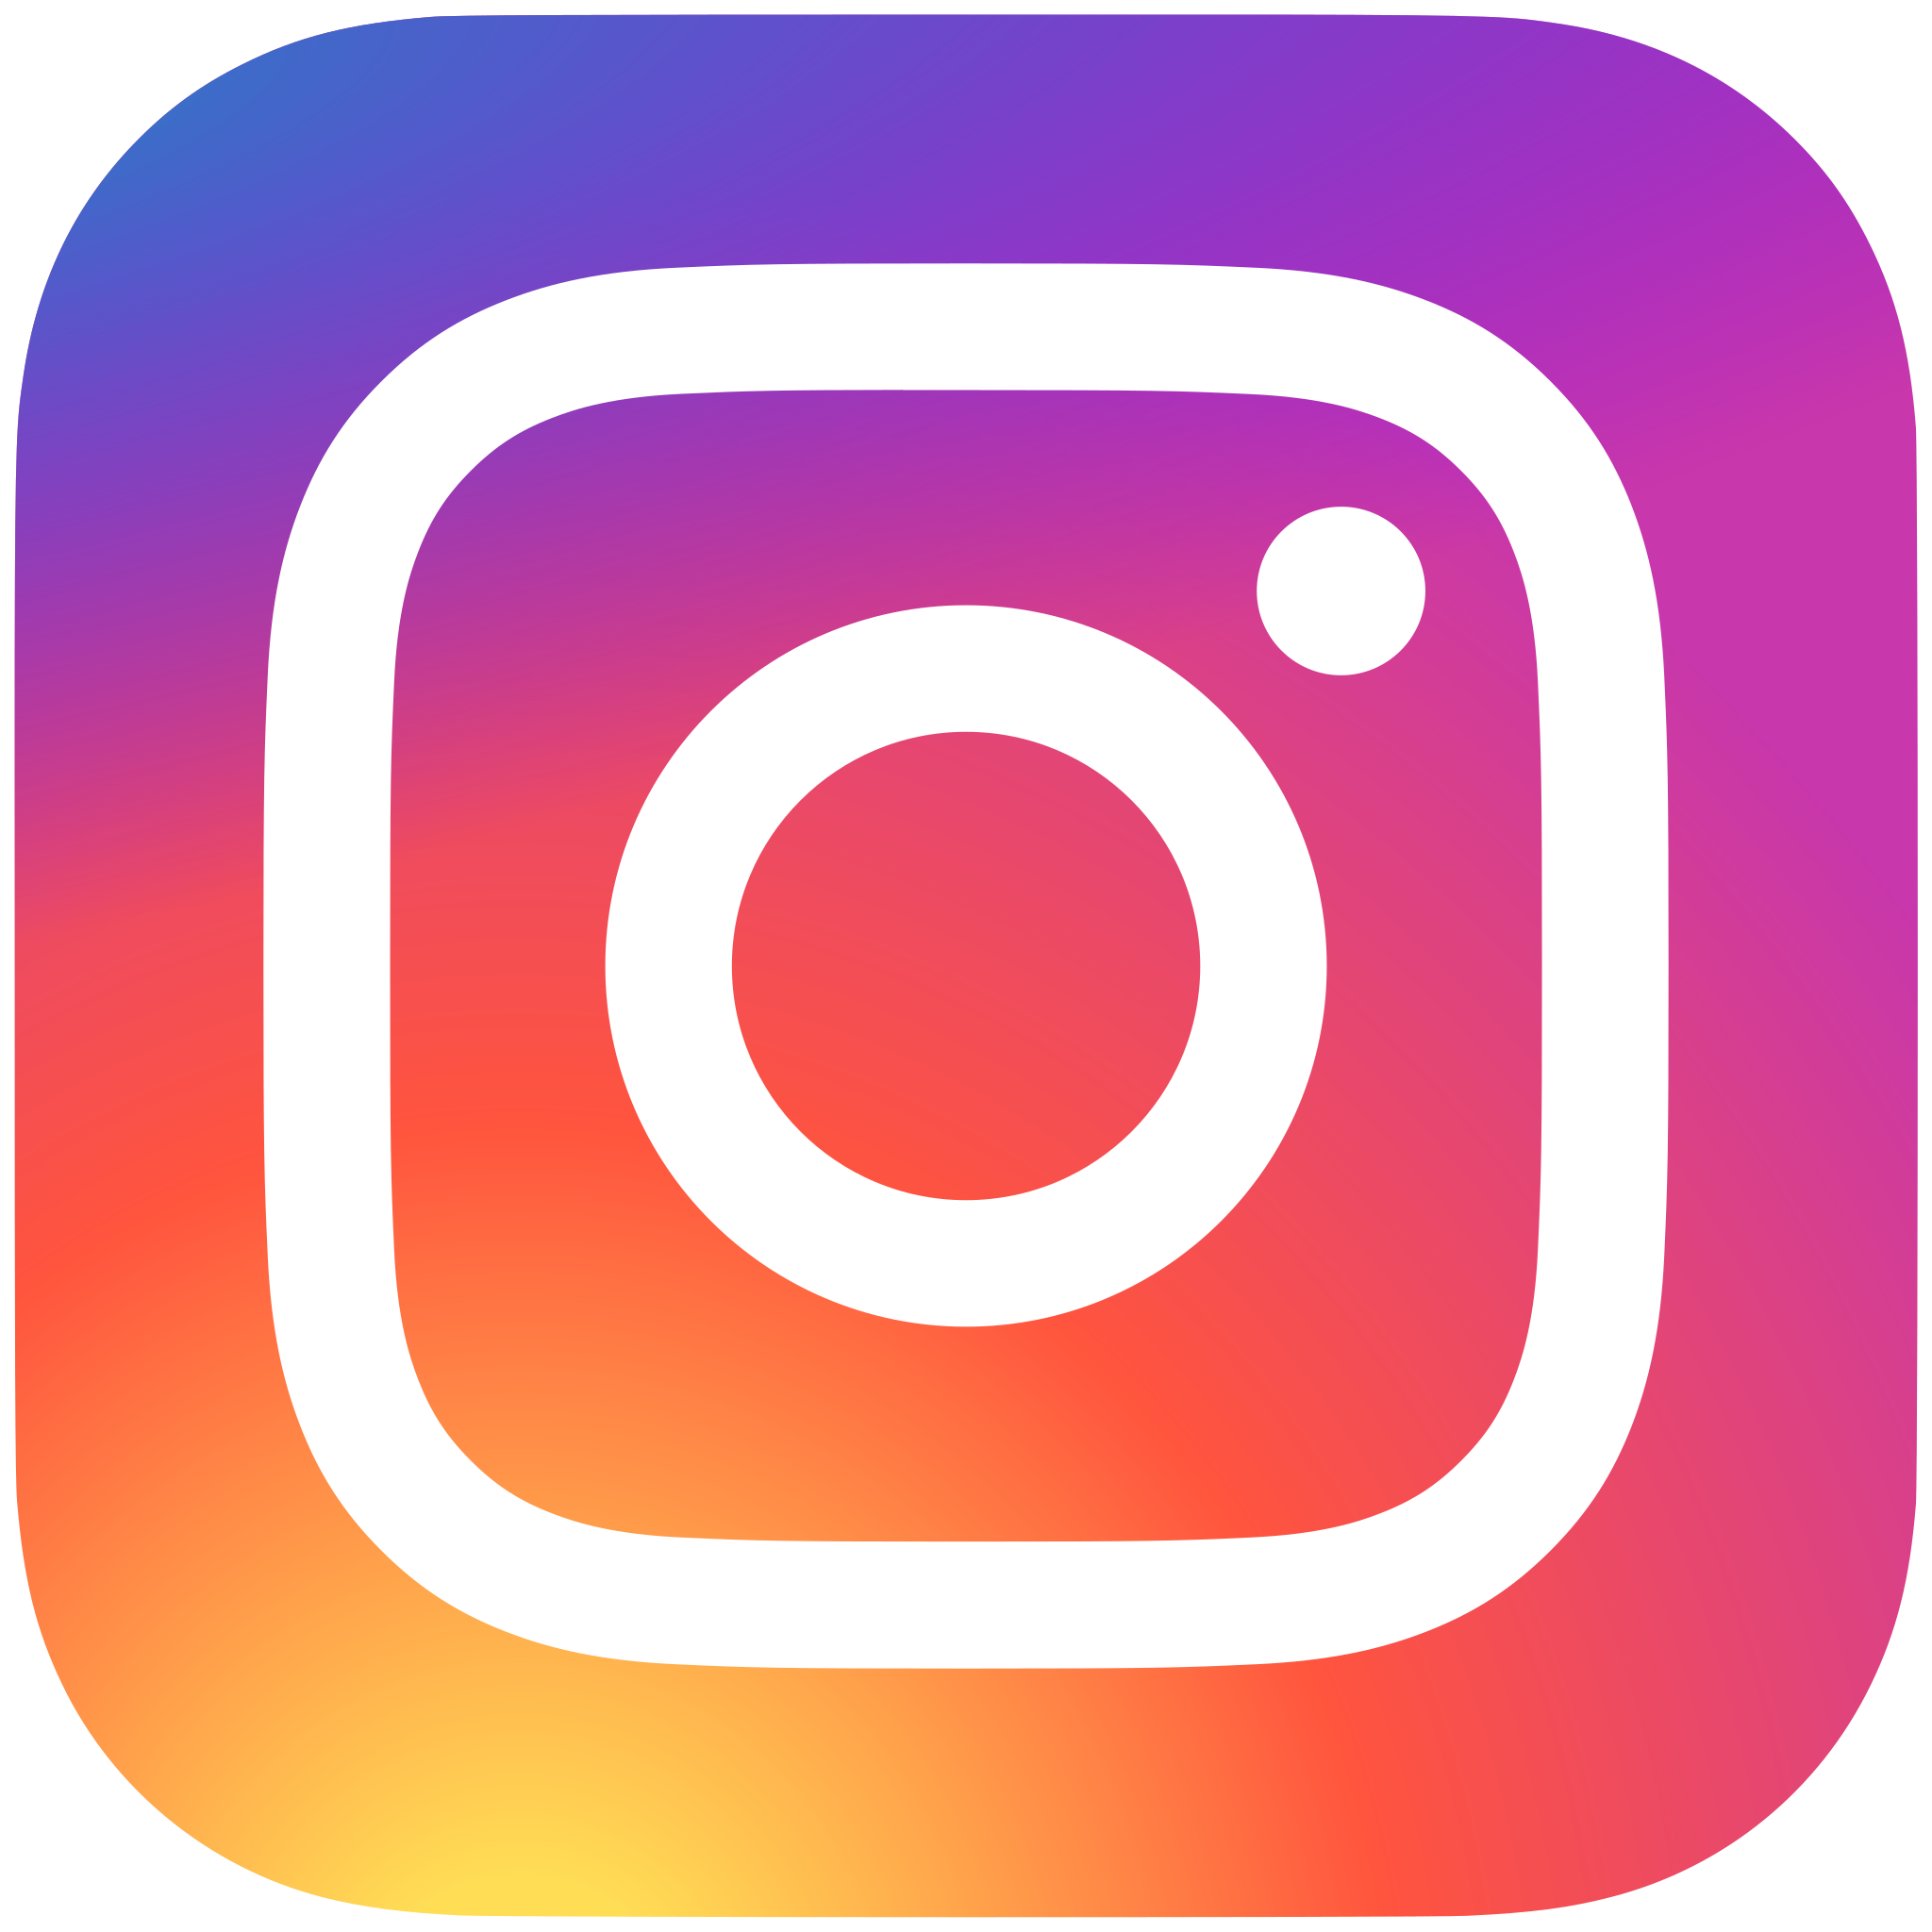 [https://www.instagram.com/fglongatt/](https://www.instagram.com/fglongatt/) 